# **INSTITUTO TECNOLÓGICO DE AERONÁUTICA **

# **CCI-22 - Professor Victor Curtis **

# **Pedro Luchiari de Carvalho - Turma 4 **

# **Relatório 4 - Interpolação**

## Questão 1 - Respostas

x=[-7 -4 -2 1 2];
y=[-1 -3 1 0 0.5];
Vandermonde(x,y);

a0 = 0.78889
a1 = -0.89167
a2 = -0.11528
a3 = 0.19167
a4 = 0.02639


## Questão 2 - Respostas

format long
x=[-1 0 1 2 3];
y=[1 1 0 -1 -2];
TDD(x,y);

b =      1     0     0     0     0
     1     0     0     0     0
     0     0     0     0     0
    -1     0     0     0     0
    -2     0     0     0     0


Ordem 0
1
1
0
-1
-2
Ordem 1
0
-1
-1
-1
Ordem 2
-5.000000e-01
0
0
Ordem 3
1.666667e-01
0
Ordem 4
-4.166667e-02


## Questão 3

%Item a:
Vx = linspace(-1, 0);

%Item b:
for i = 1 : 100
    Vf(i) = f(Vx(i));
end

%Item c:
for i = 1 : 100
    Vg(i) = g(Vx(i));
end

%Item d:
p = polyfit(Vx, Vf, 2);
for i = 1 : 100
    Vp(i) = polyval(p, Vx(i));
end

%Item e:
dif_max_f_g = 0;
for i = 1 : 100
    if abs(Vf(i) - Vg(i)) > dif_max_f_g
        dif_max_f_g = abs(Vf(i) - Vg(i));
    end
end
disp(dif_max_f_g);

   0.398549744827224




%Item f:
dif_max_f_p = 0;
for i = 1 : 100
    if abs(Vf(i) - Vp(i)) > dif_max_f_p
        dif_max_f_p = abs(Vf(i) - Vp(i));
    end
end
disp(dif_max_f_p);

   0.402525398094220




%Item g:
fplot(@(x) g(x), [-1, 0])

hold on
fplot(@(x) f(x), [-1, 0])

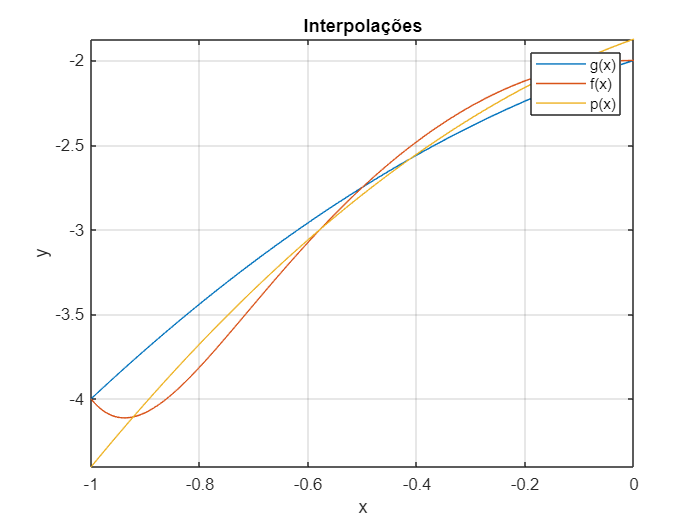

hold on
fplot(@(x) polyval(p, x), [-1, 0])
grid on
title('Interpolações')
xlabel('x');
ylabel('y');
legend('g(x)', 'f(x)', 'p(x)');

## Definições das funções usadas:

function Vandermonde(x,y)
    n=length(x);
    for i=0:n-1
        for j=1:n
            A(i+1,j)= x(i+1)^(j-1);
        end
    end
    b=y';
    a=A\b;
    for i=0:n-1
        fprintf('a%d = %.5f\n',i,a(i+1));
    end
end

function TDD(x,y)
    n=length(x);
    b=zeros(n,n);
    b(:,1)=y(:)
    for j=2:n
        for i=1:n-j+1
            b(i,j) = (b(i+1,j-1)-b(i,j-1))/(x(i+j-1)-x(i));
        end
    end
    for i=1:n
        fprintf('Ordem %d\n',i-1);
        for j=1:n
            fprintf('%d\n', b(j,i));
        end
        n=n-1;
    end
end

%funções definidas no enunciado da questão 3:

function d = f(x)
    d = x^10 - 3*x^2 - 2;
end

function d = g(x)
    d = -1.004*x^2 + 0.996*x - 2;
end

## Discussão:

As questões 1 e 2 tratam de diferentes métodos de interpolação, que cumprem bem o papel de descrever uma função contínua com base em pontos dados. Na questão 3, com base em um conjunto discreto de valores calculados a partir de um polinômio de décimo grau, fazemos uma interpolação com um polinômio de segundo grau. Tal interpolação apresenta um erro absoluto máximo superior ao de uma outra função de segundo grau testada, a saber, a função g.